Sydney_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/Australia/Sydney/rozelle-sydney east, australia-air-quality.csv";
Melbourne_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/Australia/Melbourne/melbourne-cbd, australia-air-quality.csv";

SY_AQ_Table = AQ_table(Sydney_Path);
MEL_AQ_Table = AQ_table(Melbourne_Path);

[SY_AQ_Table, MEL_AQ_Table] = same_dates(SY_AQ_Table, MEL_AQ_Table)

SY_AQ_Table = 976×8 table
       date        pm25    pm10    o3     no2    so2    co     AQ 
    ___________    ____    ____    ___    ___    ___    ___    ___

    12-Jun-2020     21     NaN     NaN    NaN    NaN    NaN     21
    11-Jun-2020     22     NaN      19      9      1      2     22
    10-Jun-2020     18     NaN     NaN    NaN    NaN    NaN     18
    09-Jun-2020     16       5      20     10      1      2     20
    08-Jun-2020     62     NaN      19      3      1    NaN     62
    07-Jun-2020     54      31      18      8      1      4     54
    06-Jun-2020     46      21      15     14      1      5     46
    05-Jun-2020     17      22       8     19      1      4     19
    04-Jun-2020     15      15 

MEL_AQ_Table = 976×8 table
       date        pm25    pm10    o3     no2    so2    co     AQ 
    ___________    ____    ____    ___    ___    ___    ___    ___

    12-Jun-2020     52     NaN     NaN    NaN    NaN    NaN     52
    11-Jun-2020     48     NaN     NaN    NaN    NaN    NaN     48
    10-Jun-2020     49     NaN     NaN    NaN    NaN    NaN     49
    09-Jun-2020     40     NaN     NaN    NaN    NaN    NaN     40
    08-Jun-2020     15     NaN     NaN    NaN    NaN    NaN     15
    07-Jun-2020     50     NaN     NaN    NaN    NaN    NaN     50
    06-Jun-2020     65     NaN     NaN    NaN    NaN    NaN     65
    05-Jun-2020     25     NaN     NaN    NaN    NaN    NaN     25
    04-Jun-2020     28     NaN


diff = SY_AQ_Table.AQ - MEL_AQ_Table.AQ 

diff =    -31
   -26
   -31
   -20
    47
     4
   -19
    -6
   -11
     1


Same_Value_pct = (length(diff(diff==0))/length(diff))*100
SY_Higher_pct = (length(nonzeros(diff(diff>0)))/length(diff))*100

SY_Higher_pct = 56.8648

MEL_Higher_pct = (length(nonzeros(diff(diff<0)))/length(diff))*100

MEL_Higher_pct = 40.5738

Same_Value = 25

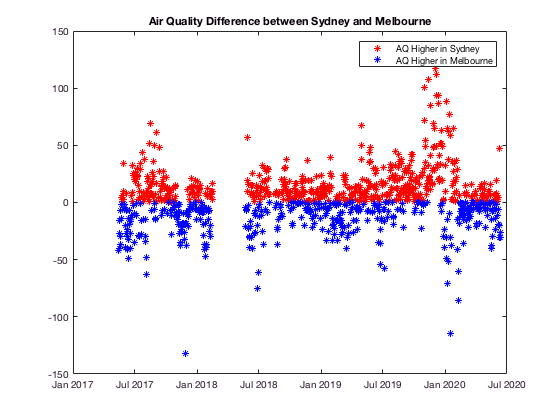

SY_Higher = zeros(length(diff), 1);
MEL_Higher = zeros(length(diff), 1);

for i = 1:length(diff)
    if diff(i)>0
        SY_Higher(i) = diff(i);
        MEL_Higher(i) = nan; 
    end 
    if diff(i)<0
        SY_Higher(i) = nan; 
        MEL_Higher(i) = diff(i);
    end 
    if diff(i)==0
        SY_Higher(i) = 0;
        MEL_Higher(i) = 0;
    end 
        
end 

plot(SY_AQ_Table.date, SY_Higher, '*r')
hold on; 
plot(MEL_AQ_Table.date, MEL_Higher, '*b')
ylim([-150 150])
title('Air Quality Difference between Sydney and Melbourne')
legend('AQ Higher in Sydney', 'AQ Higher in Melbourne')

function AQ_Table = AQ_table(filename)
    % Read file into a table 
    AQ_Table = readtable(filename);
    % Create an air quality column (Max value of all columns per day)
    AQ_Col = max([AQ_Table.pm25, AQ_Table.o3, AQ_Table.no2, AQ_Table.so2, AQ_Table.co], [], 2);
    AQ_Table.AQ = AQ_Col;
    % Change dates to matlabs datetime object
    AQ_Table.date = datetime(AQ_Table.date,'InputFormat','yyyy/MM/dd');
    % Sort by date 
    [~,idx] = sort(AQ_Table.date, 'descend');
    AQ_Table = AQ_Table(idx,:);
end 

function [Table1_o Table2_o] = same_dates(Table1, Table2) 
    % Setting the length of both tables to that of the shorter table 
    max_len = min(length(Table1.date), length(Table2.date));
    Table1 = Table1(1:max_len, :);
    Table2 = Table2(1:max_len, :);
    
    % Finding all the common dates between both tables 
    [~, idx1, idx2] = intersect(Table1.date, Table2.date, 'stable');
    
    % Indexing the tables to only include common dates 
    Table1_o = Table1(idx1, :);
    Table2_o = Table2(idx2, :);
end 
